# Rotary Inverted Pendulum System Identification via Constrained Non Linear Optimization and Simulation Error Criterion

The main advantage of employing a simulation error method for system identification is that the procedure allow to get models which are less influenced by fast sampling times and large measurement noise.

## Unconstrained System identification via S.E.M.

addpath("../Model/"); % NL equations
addpath("../optimization/UncOpt/"); % optimization routines
addpath("../optimization/ConsOpt/");
addpath("../Manual_Validation/esp/theta_esp/"); % experimental data
addpath("../Manual_Validation/esp/alpha_esp/");
addpath("../Manual_Validation/esp/theta_d_esp/");
addpath("../Manual_Validation/esp/alpha_d_esp/");
addpath("../Manual_Validation/esp/t_esp/");
addpath("../Manual_Validation/esp/voltage_esp/");
addpath("../")
startUp % load datasheet model parameter values

### Load the Data

Also need to add a procedure to save the results consistently and link the identification esults to the experiment used to perform identification.

Remark: for consistency of use of the optimization toolboxes we will denote in the following the state as $z$ and the decision variables as $x$.

train_exp = 50;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(train_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(train_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(train_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(train_exp)+'.mat')));
alpha_dot=cell2mat(struct2cell(load('alpha_d_esp'+ string(train_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];

% check if voltage was measured before or after -1 gain
if uin(1,100) > 0 && theta(1,100) <= 0 || uin(1,100) < 0 && theta(1,100) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % consider negative voltages
end

downsample_factor = 1;
Ts = 0.002*downsample_factor; % sampling time of the simulation/data acquisition process
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions
% z0 = [0; 0; 0; 0];

### Analysis & preprocessing of Training Data

data = iddata(ymeas(1:2,:)',uin',Ts,'InputName','V','OutputName',{'theta','alpha'},'InterSample','foh') % wants column vectors

data =

Time domain data set with 18285 samples.
Sample time: 0.002 seconds               
                                         
Outputs      Unit (if specified)         
   theta                                 
   alpha                                 
                                         
Inputs       Unit (if specified)         
   V                                     
                                         


#### In time domain:

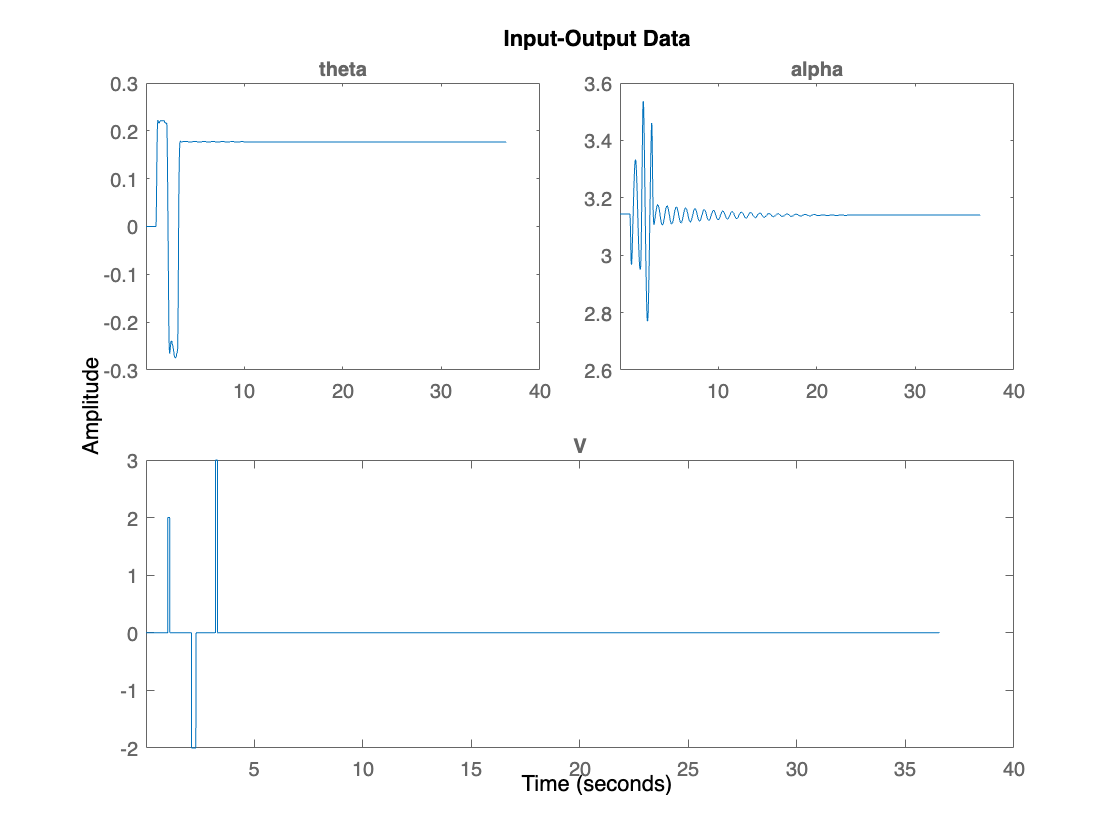

plot(data)

#### In the frequency domain

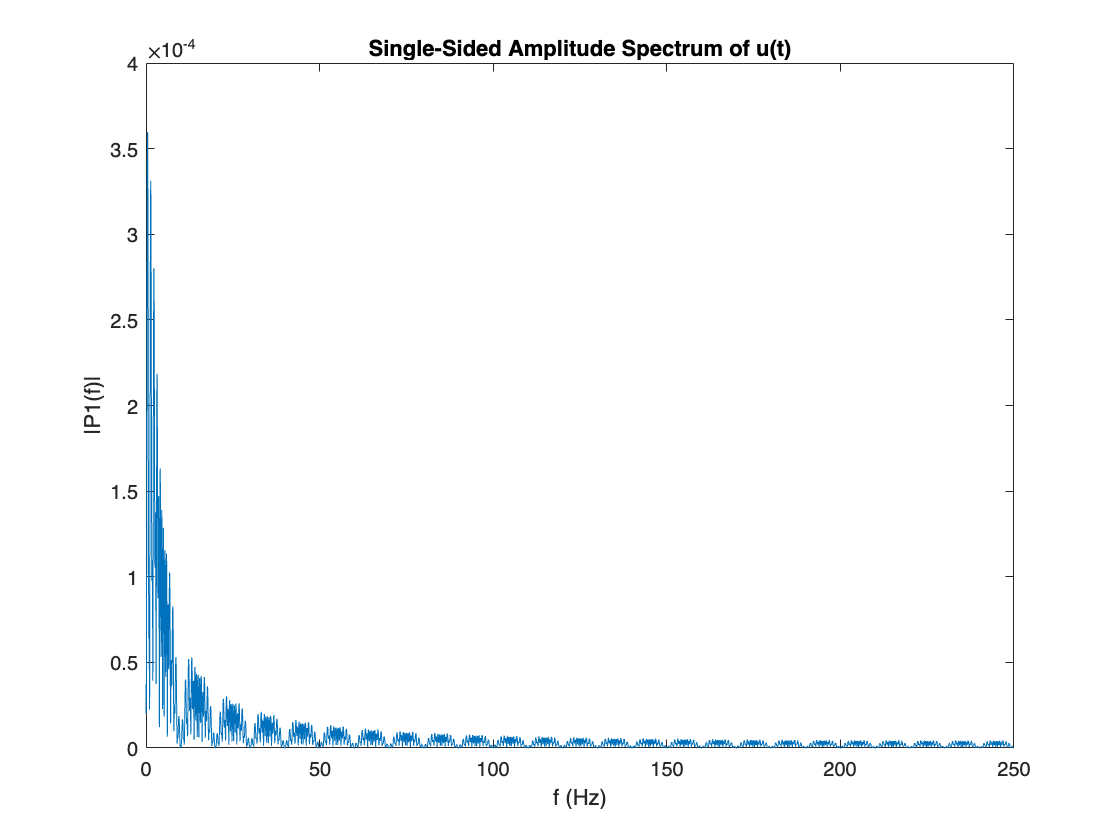

Fs = 1/Ts;            % Sampling frequency                                % Sampling period       
L = length(Time_vec);             % Length of signal
t = Time_vec;       % Time vector
Y = fft(data);
% uin - input Voltage
P2 = abs(Y.InputData/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of u(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

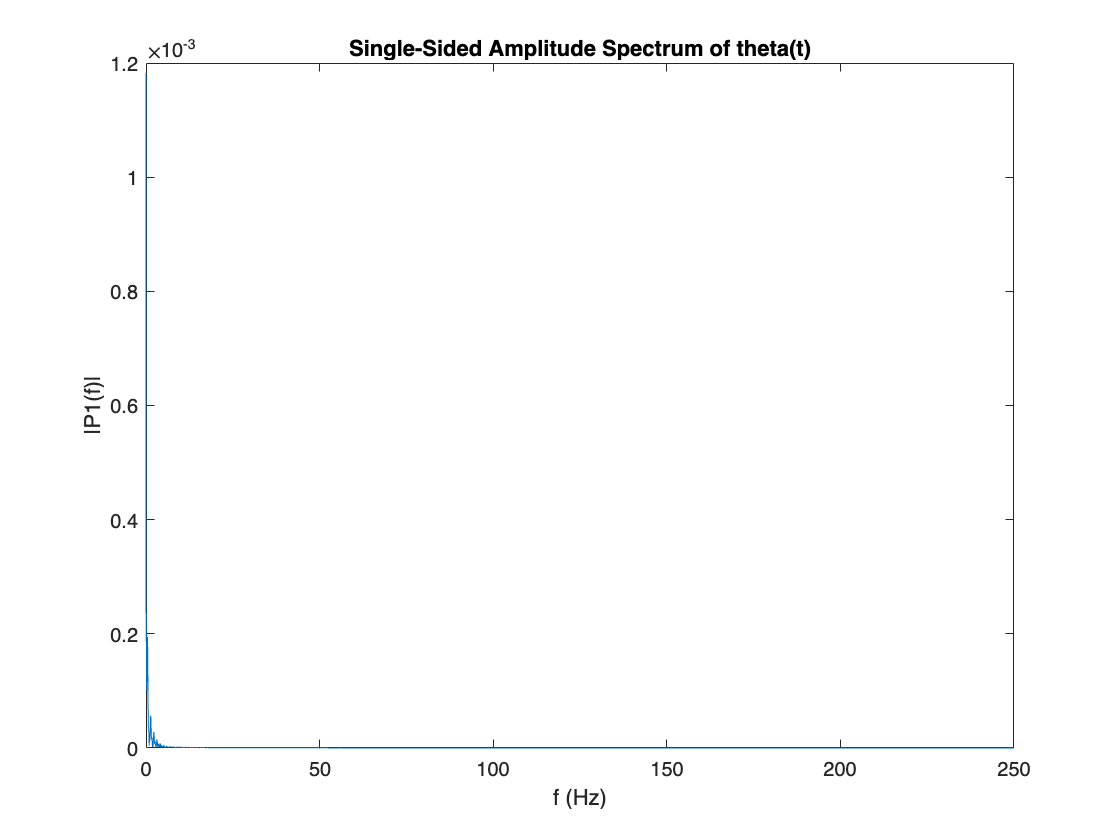

% y1 - alpha
P2 = abs(Y.OutputData(:,1)/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:floor(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of theta(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

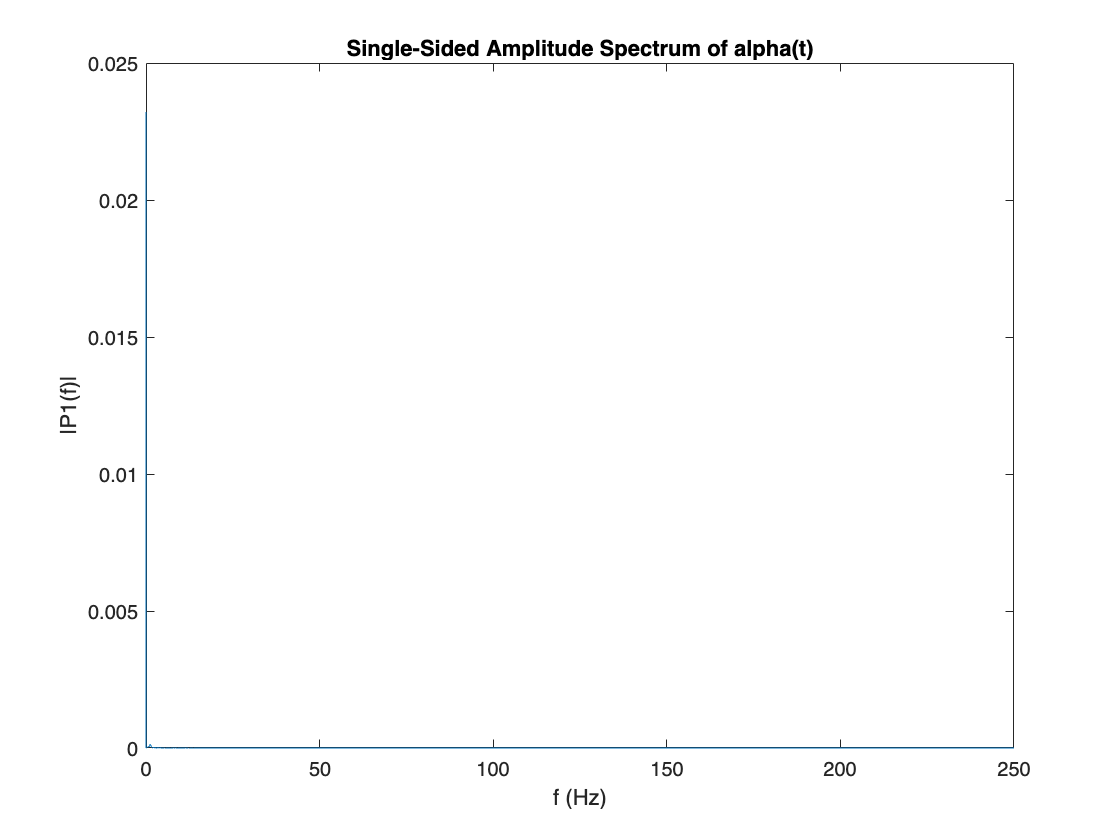


% y2
P2 = abs(Y.OutputData(:,2)/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:floor(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of alpha(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

advice(data);

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 2 output(s), 18285 samples 
and 1 experiment(s).

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may do so using a TrendInfo object with 
DETREND command, or during estimation using the "InputOffset" and 
"OutputOffset" estimation options.
2. There is an integrator in the system, and the input and output levels are 
essential to describe the effect of the integration.
3. You are going to use the data to estimate nonlinear ARX models.

Excitation level in data:
-------------------------
The input has all its 

### Weighting matrices for cost function and scaling factor

We should check the orders of magnitude of measured variables in order to avoid numerical issues, it would be great to normalize through a scaling factor.

Q = eye(4);
%Q(1,1) = 1e5;
%Q(2,2) = 1e5;

scaling =ones(10,1); 
% scaling = [1e3 1e3 1e3 1e3 1e1 1 1e1 1e1 1e3 1e3]'; % needed only if the parameters to identify are of differnet
% orders of magnitude

### Initialize parameter estimates

we want to estimate the following physical parameters: 


$$B_p ,B_r ,J_{a\;} ,J_p ,l_p ,R_m ,\eta_g ,\eta_m ,k_m ,k_t$$


in a future version we could add the positions of the centers of mass: $l_p$

% x0 = rand([10,1]);
load("x0_BFGS.mat")
% x0 = [2e-3;2e-3;2e-3;1.5e-3;0.3;R_m;eta_g;(eta_m);(k_m);(k_t)];

## Constrained Optimization

The unconstrained optimization above, despite giving good results leverages negative numbers which are unfeasible for physical quantities such as moment of inertia.

In the following we will try to introduce some linear constraints on parameter values.

### Define the linear inequality constraints matrices 

From physics we impose some limit values for the physical parameters of the system, these limits are here formulated as **linear inequality constraints **of the form $C\;x\ge d$.

The constrained has been placed on the parameters with the highest uncertainty, this uncertainty can be found int the following datasheets:

[https://important-tray-3cf.notion.site/System-Physical-Parameters-Values-from-literature-796efa849a1a48a3a09d2c81c7839a15](https://important-tray-3cf.notion.site/System-Physical-Parameters-Values-from-literature-796efa849a1a48a3a09d2c81c7839a15)

C = zeros(20,10);
C(1,1) = 1;
C(2,1) = -1;
C(3,2) = 1;
C(4,2) = -1;
C(5,3) = 1;
C(6,3) = -1;
C(7,4) = 1;
C(8,4) = -1;
C(9,5) = 1;
C(10,5) = -1;
C(11,6) = 1;
C(12,6) = -1;
C(13,7) = 1;
C(14,7) = -1;
C(15,8) = 1;
C(16,8) = -1;
C(17,9) = 1;
C(18,9) = -1;
C(19,10) = 1;
C(20,10) = -1;

d = [1e-4; -3e-3; 1e-4; -3e-3; 1e-4; -2.5e-3; 1e-4; -1.7e-3;1e-4;-0.337;R_m-(R_m*0.12);-(R_m+(R_m*0.12));eta_g-(eta_g*0.1);-(eta_g+(eta_g*0.1));eta_m-(eta_m*0.1);-(eta_m+(eta_m*0.1));k_m-(k_m*0.12);-(k_m+(k_m*0.12));k_t-(k_t*0.12);-(k_t+(k_t*0.12))];
% d = [1e-4; -3e-3; 1e-4; -3e-3; 1e-4; -2.5e-3; 1e-4; -1.7e-3;1e-4;-0.337;1e-4;-(R_m+(R_m*0.12));1e-4;-(eta_g+(eta_g*0.1));1e-4;-(eta_m+(eta_m*0.1));1e-4;-(k_m+(k_m*0.12));1e-4;-(k_t+(k_t*0.12))];

### Optimization routine

% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod    =   'GN';
% myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-9;
myoptions.ls_tkmax      =	1;          
myoptions.ls_beta       =	0.5;
myoptions.ls_c          =	0.1;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';
myoptions.GN_sigma      =   1e-6; % sufficiently small
myoptions.GN_funF       =   @(x)Rot_pend_sim_err(x,z0,uin,ymeas,th,Ts,Q,scaling);

% Run solver
[xstar,fxstar,niter,exitflag,xsequence] = myfmincon(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,[],[],C,d,0,0,myoptions);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.05068e-02   3.07652e-02   0.00000e+00   -1.91908e+00   1.00000e+00    1.00000e+00               0
        1    3.09055e+00   5.44959e-03   0.00000e+00    3.76960e-09   8.22969e-01    1.31684e+00               0
        2    4.70554e-01   3.22086e-03   0.00000e+00    1.37632e-08   4.08971e-01    2.32676e-02               0
        3    4.68799e-01   3.13551e-03   0.00000e+00    3.54407e-05   2.64986e-02    3.22314e-03               2
        4    1.97018e-01   2.88290e-03   0.00000e+00    1.83373e-05   8.05663e-02    1.52921e-03               1
        5    1.11276e+00   2.50598e-03   0.00000e+00    1.26282e-06   1.30741e-01    1.67566e-02               0
        6    2.55663e+00   2.29357e-03   0.00000e+00    6.73525e-07   8.47629e-02    8.78666e-03               1
        7    1.24210e+00   1.80956e-03   0.00000e+00    1.74445e-08   2.11029e-01    8.23701e-03

% matlab built in optimization function
% lb = [1e-4; 1e-4; 1e-4; 1e-4;1e-4;R_m-(R_m*0.12);eta_g-(eta_g*0.1);eta_m-(eta_m*0.1);k_m-(k_m*0.12);k_t-(k_t*0.12)];
% ub = [3e-3;3e-3;2.5e-3;1.7e-3;0.337;(R_m+(R_m*0.12));(eta_g+(eta_g*0.1));(eta_m+(eta_m*0.1));(k_m+(k_m*0.12));(k_t+(k_t*0.12))];
% options = optimoptions('fmincon','Display','iter','Algorithm','interior-point', ...
%     'UseParallel',true,'EnableFeasibilityMode',true, ...
%     'FiniteDifferenceType','central','MaxFunctionEvaluations',1e6);
% [xstar,fval,exitflag,output] = fmincon(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,C,d,[],[],lb,ub,[],options);
% Results

[xstar./scaling [B_p;B_r;J_a;J_p;l_p;R_m;eta_g;eta_m;k_m;k_t]]

ans =     0.0004    0.0024
    0.0021    0.0024
    0.0001    0.0020
    0.0008    0.0012
    0.0292    0.1560
    2.3834    2.6000
    0.9339    0.9000
    0.7077    0.6900
    0.0085    0.0077
    0.0074    0.0077


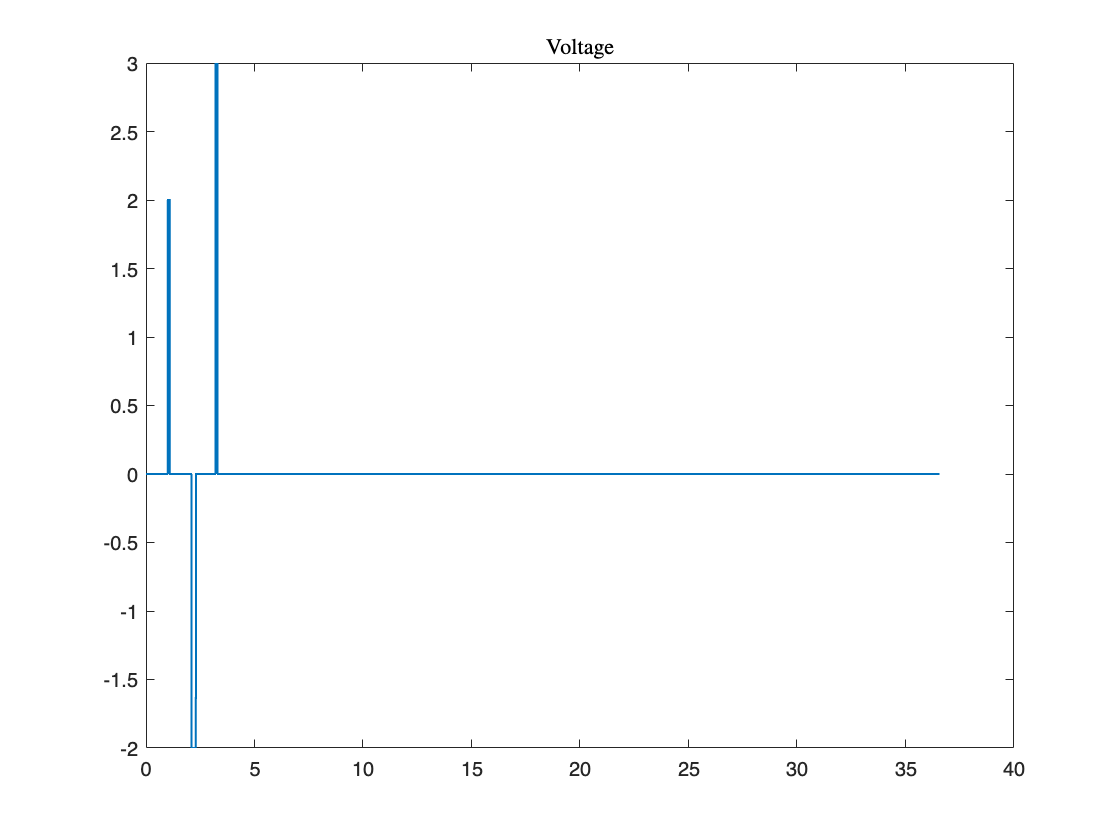

[~,ysim] = Rot_pend_sim_cost(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,uin,LineWidth=1);
title('Voltage','Interpreter','latex')

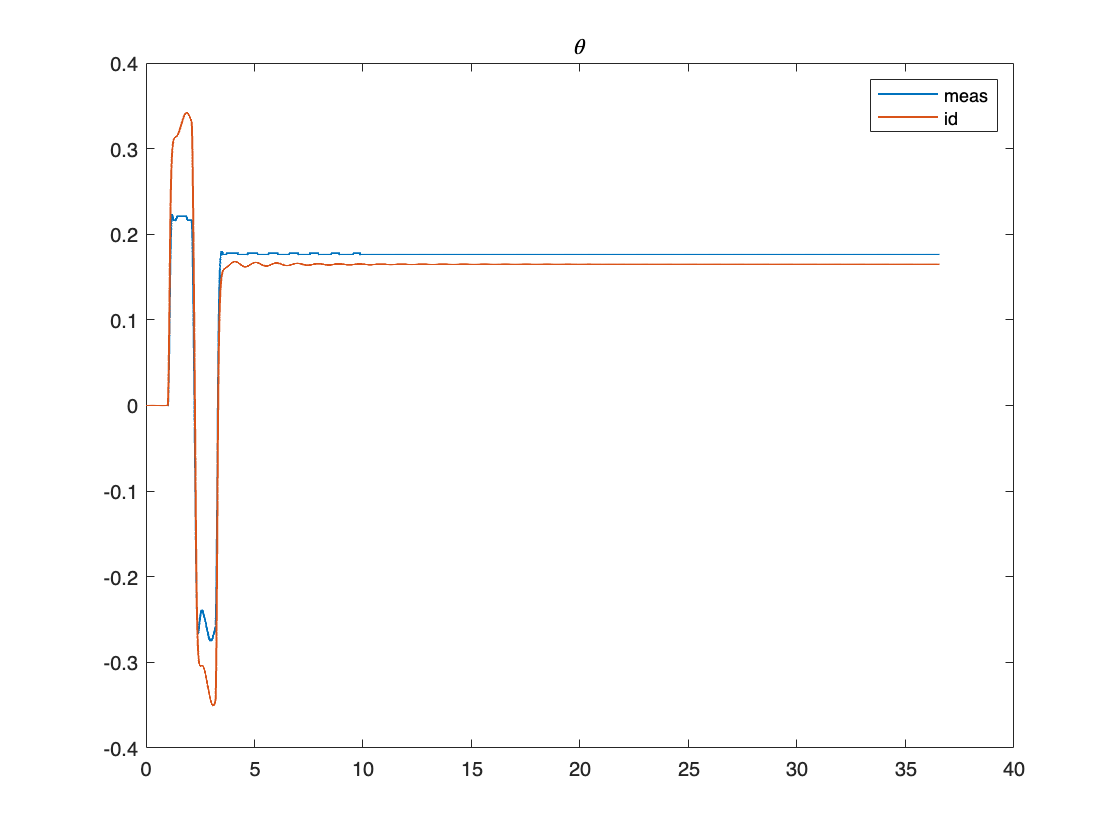


figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:),LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('meas','id')

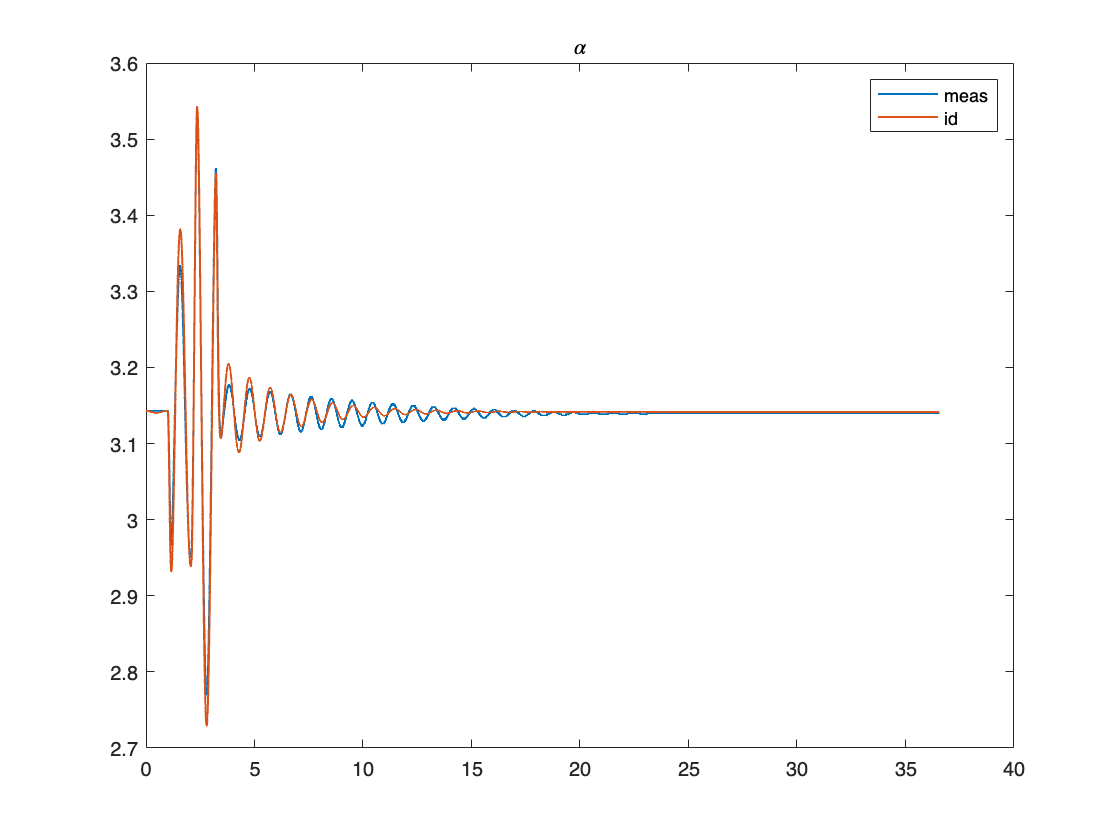

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('meas','id')

% figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))
% figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))


#### Performances on the training set

% delayest(data) % must use data with one input and one output
Order         = [2 size(uin,1) 4]; % Model orders [ny nu nx].
id_param = th;
% substitute identified values
id_param(1:5) = xstar(1:5);
id_param(10:14) = xstar(6:10);
InitialStates = z0;
nlgr_m    = idnlgrey('rot_pend_m', Order, id_param, InitialStates, 0)


nlgr_m =

Continuous-time nonlinear grey-box model defined by 'rot_pend_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p14)
    y(t) = H(t, u(t), x(t), p1, ..., p14) + e(t)

 with 1 input(s), 4 state(s), 2 output(s), and 14 free parameter(s) (out of 14).

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


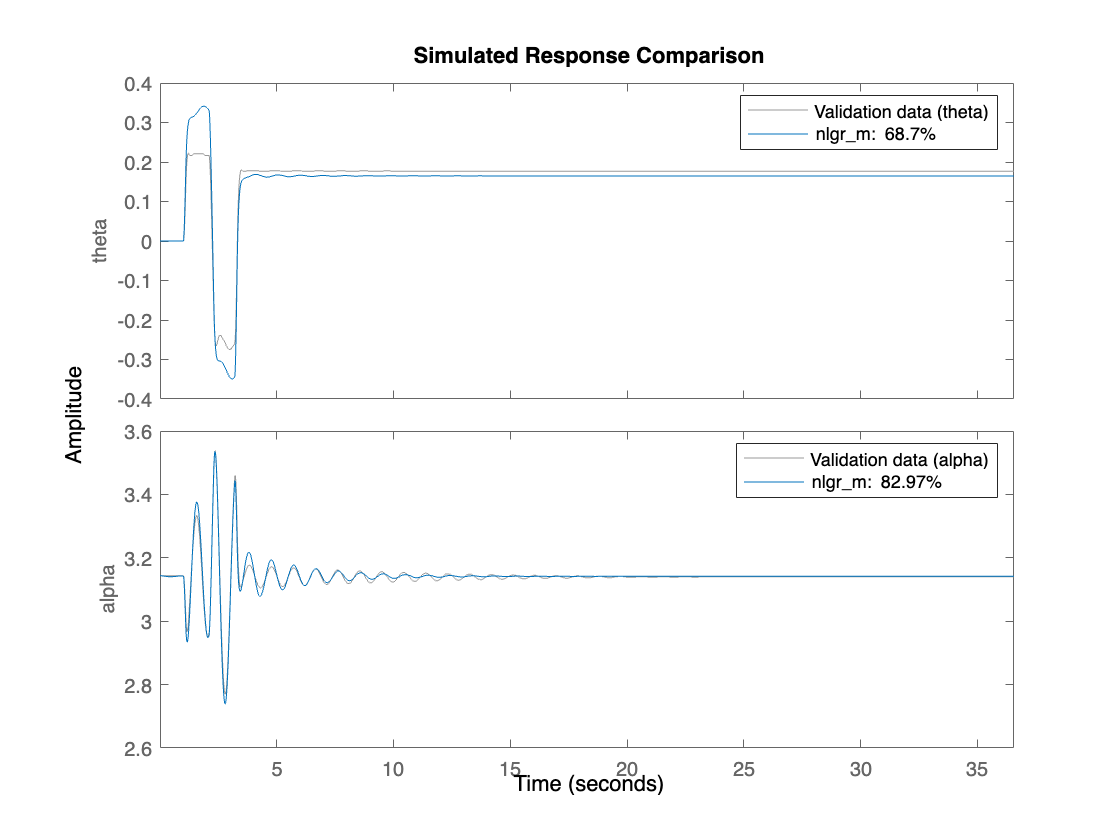

compare(data, nlgr_m)

#### Tentative Disturbance estimation: 

Estimating a tf from theta to the unwanted oscillation component on alpha. (Not rigorous, just tentative based on literature analysis)

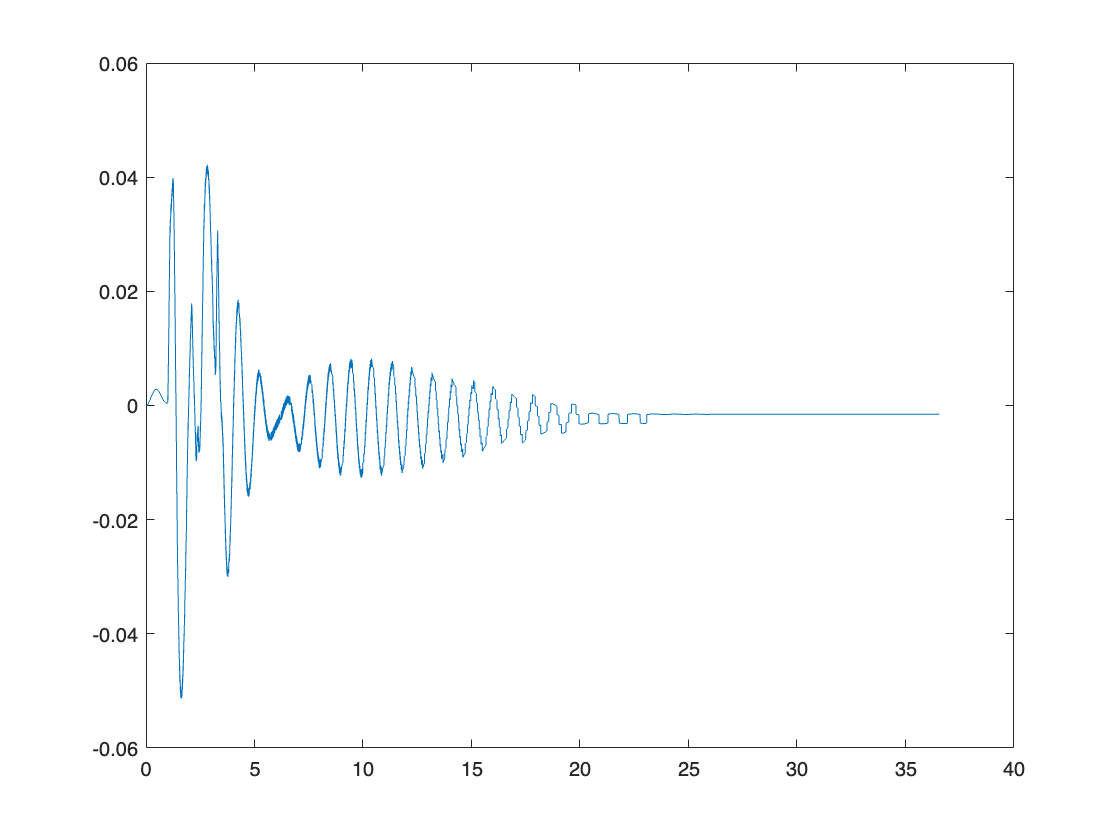

sim_alpha = ysim(2,:);
dist = ymeas(2,:) - sim_alpha;
plot(Time_vec,dist)

dist_data = iddata(dist',ymeas(1,:)',Ts); % time serie data of disturbance
advice(dist_data)

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 1 output(s), 18285 samples 
and 1 experiment(s).

All inputs in the data have been denoted as 'zero order hold' ('zoh'), i.e. 
they are assumed to be piecewise constant over the sample time.
If the input is a sampled continuous signal and you plan to build or convert to 
continuous-time models, it is recommended to mark the InterSample property as 
'First order hold': Data.InterSample = 'foh' or Data.int = {'foh','foh', ...} 
for multi-input signals.

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may do so 

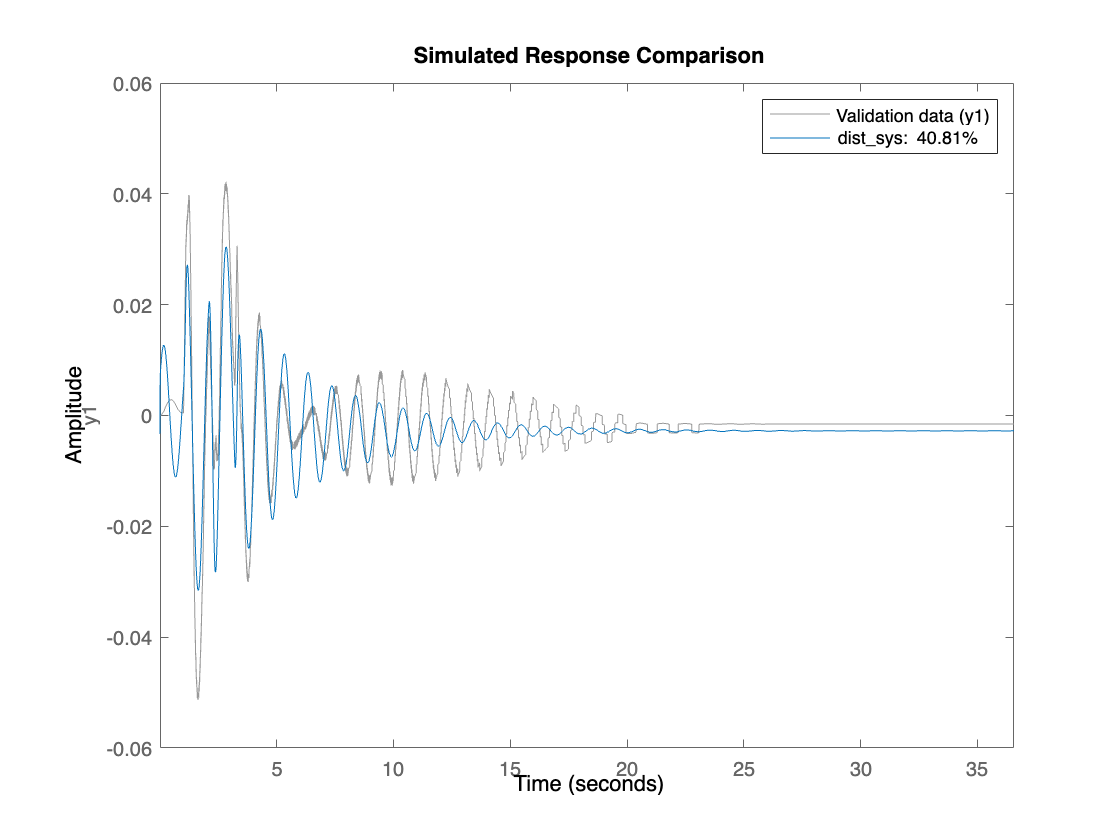

dist_sys = tfest(dist_data,3);
compare(dist_data,dist_sys)

## Validation

Here we perform the validation of the identified parameters by looking at the behaviour of the non linear model against a different sineswept.

Validation with respect to the impulse response

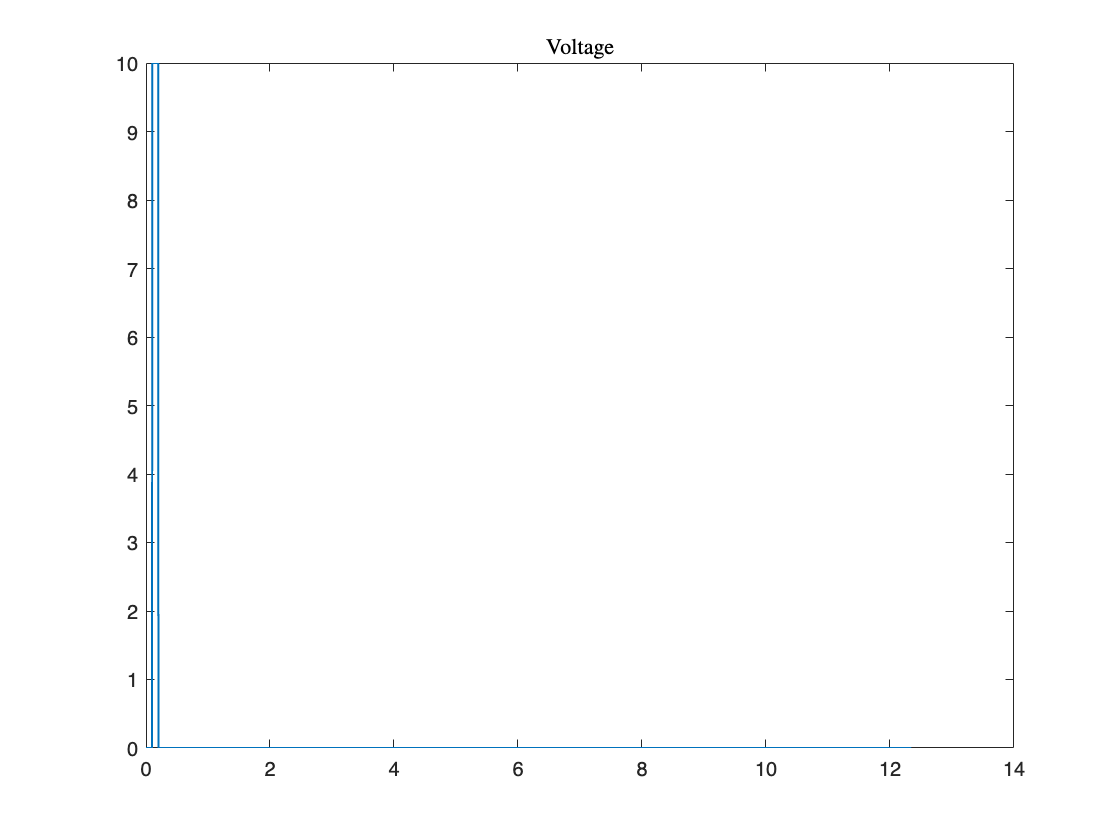

val_exp = 35;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(val_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(val_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(val_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(val_exp)+'.mat')));
alpha_dot = cell2mat(struct2cell(load('alpha_d_esp'+ string(val_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions
%z0 = [0; 0; 0; 0];
% check if voltage was measured before or after -1 gain
if uin(1,70) > 0 && theta(1,70) <= 0 || uin(1,70) < 0 && theta(1,70) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % consider negative voltages
end

% simulation of the non linear system
[~,ysim] = Rot_pend_sim_err(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,uin,LineWidth=1);
title('Voltage','Interpreter','latex')

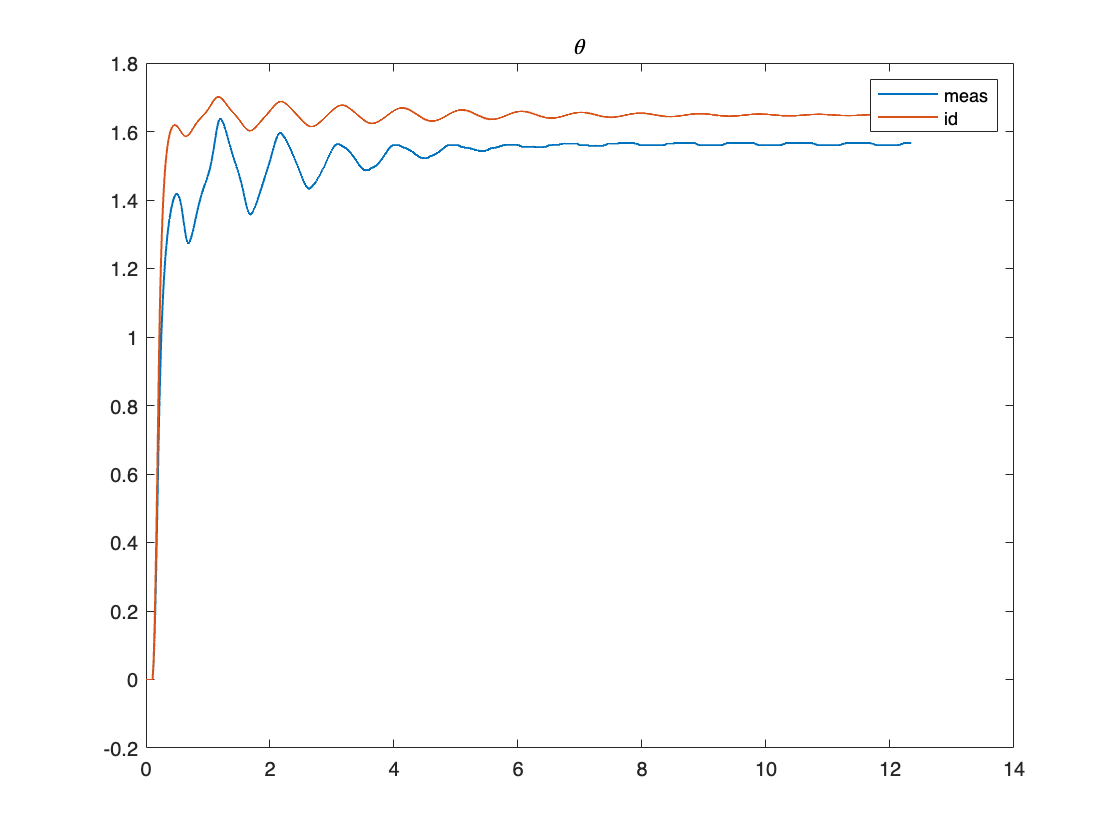

figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:),LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('meas','id')

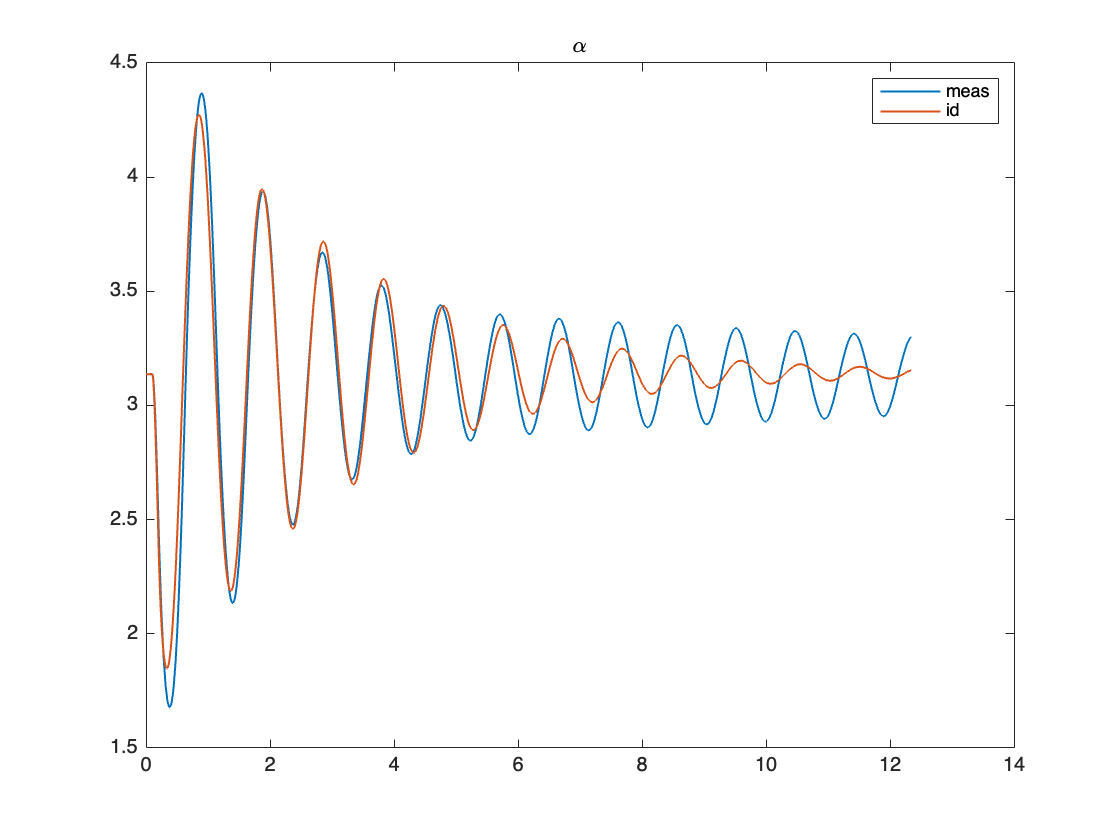

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('meas','id')

% figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))
% figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))

### Performance metrics

Here we want to assess the goodness of the identification through some metrics and also perform a residual analysis in order to assess the limit of our model and our identification procedure.

data = iddata(ymeas(1:2,:)',uin',Ts,'InputName','V','OutputName',{'theta','alpha'},'InterSample','foh') % wants column vectors

data =

Time domain data set with 6173 samples.
Sample time: 0.002 seconds              
                                        
Outputs      Unit (if specified)        
   theta                                
   alpha                                
                                        
Inputs       Unit (if specified)        
   V                                    
                                        


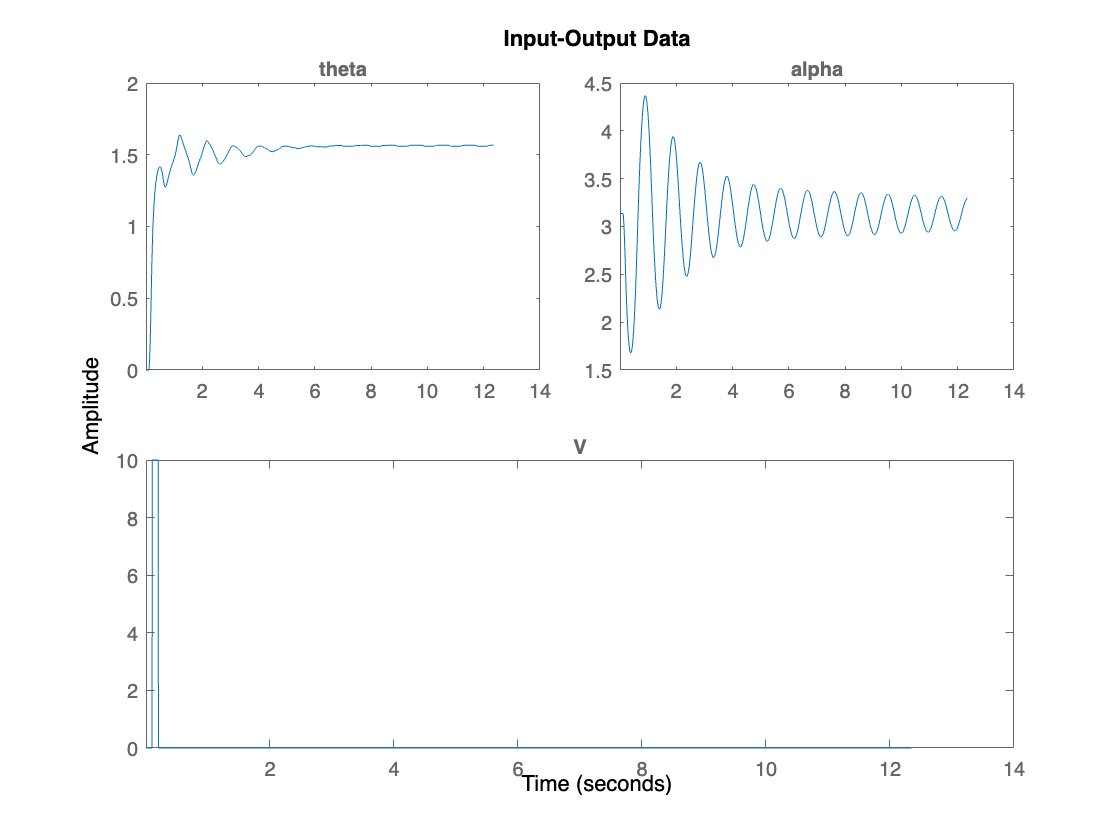

plot(data)

advice(data);

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 2 output(s), 6173 samples 
and 1 experiment(s).

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may do so using a TrendInfo object with 
DETREND command, or during estimation using the "InputOffset" and 
"OutputOffset" estimation options.
2. There is an integrator in the system, and the input and output levels are 
essential to describe the effect of the integration.
3. You are going to use the data to estimate nonlinear ARX models.

Excitation level in data:
-------------------------
The input has all its v


Order         = [2 size(uin,1) 4]; % Model orders [ny nu nx].
id_param = th;
% substitute identified values
id_param(1:5) = xstar(1:5);
id_param(10:14) = xstar(6:10);
InitialStates = z0;
nlgr_m    = idnlgrey('rot_pend_m', Order, id_param, InitialStates, 0)


nlgr_m =

Continuous-time nonlinear grey-box model defined by 'rot_pend_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p14)
    y(t) = H(t, u(t), x(t), p1, ..., p14) + e(t)

 with 1 input(s), 4 state(s), 2 output(s), and 14 free parameter(s) (out of 14).

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


% sim(nlgr_m,data)

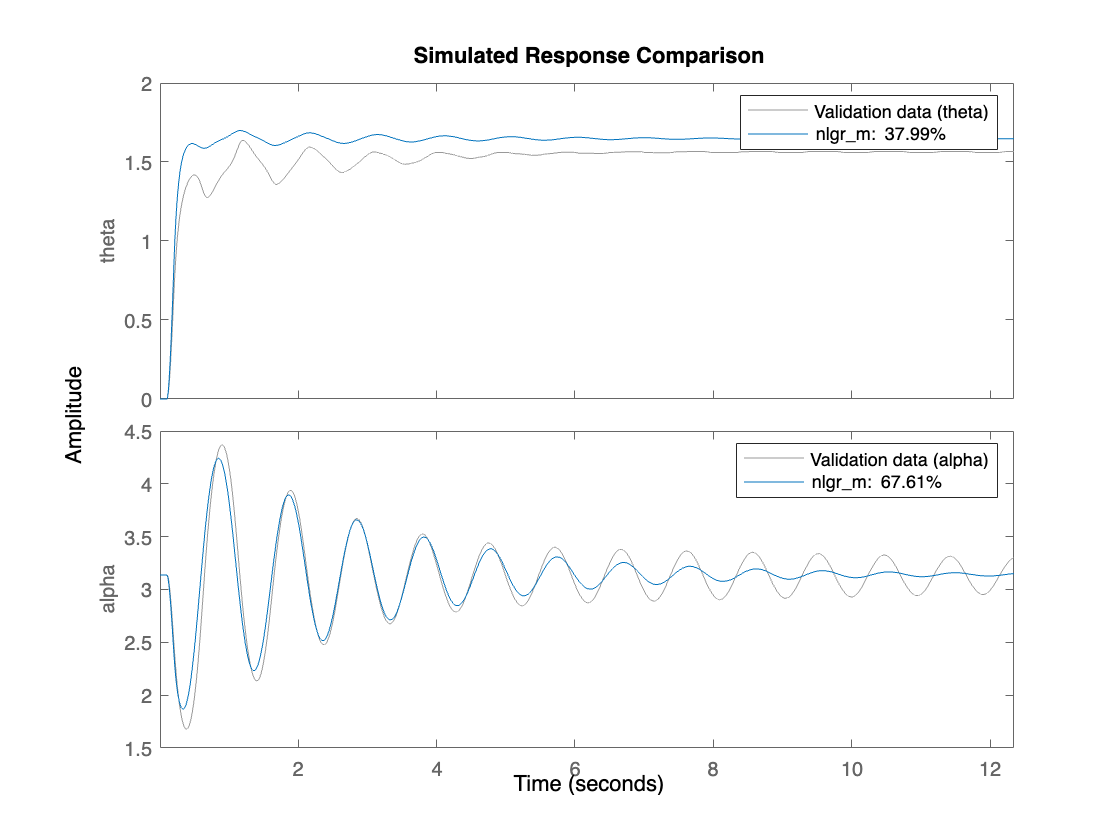

compare(data, nlgr_m)

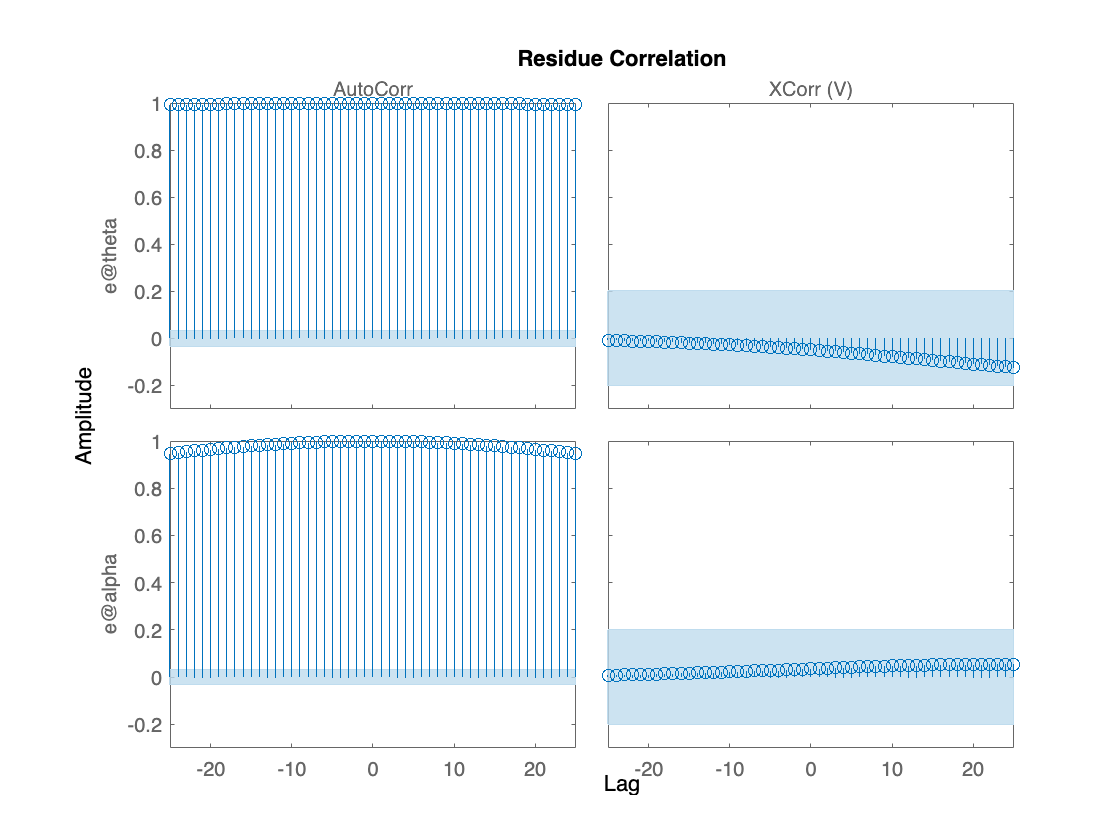

resid(data,nlgr_m)

If we look at these residual correlations, we see that the cross correlation with input is low, but the autocorrelation is high. So we can probably conclude that we're missing dynamics in the disturbance path and not in the system model.

#### Simulation taking into account for disturbance

we'll sum the disturbance to the simulated data so that we can see if the model captures better the real system behaviour

sim_alpha = ysim(2,:);
dist = ymeas(2,:) - sim_alpha;
dist_data_val = iddata(dist',ymeas(1,:)',Ts);
sim_dist = sim(dist_sys,dist_data_val) % simulated disturbance signal

sim_dist =

Time domain data set with 6173 samples.
Sample time: 0.002 seconds              
Name: dist_sys                          
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        


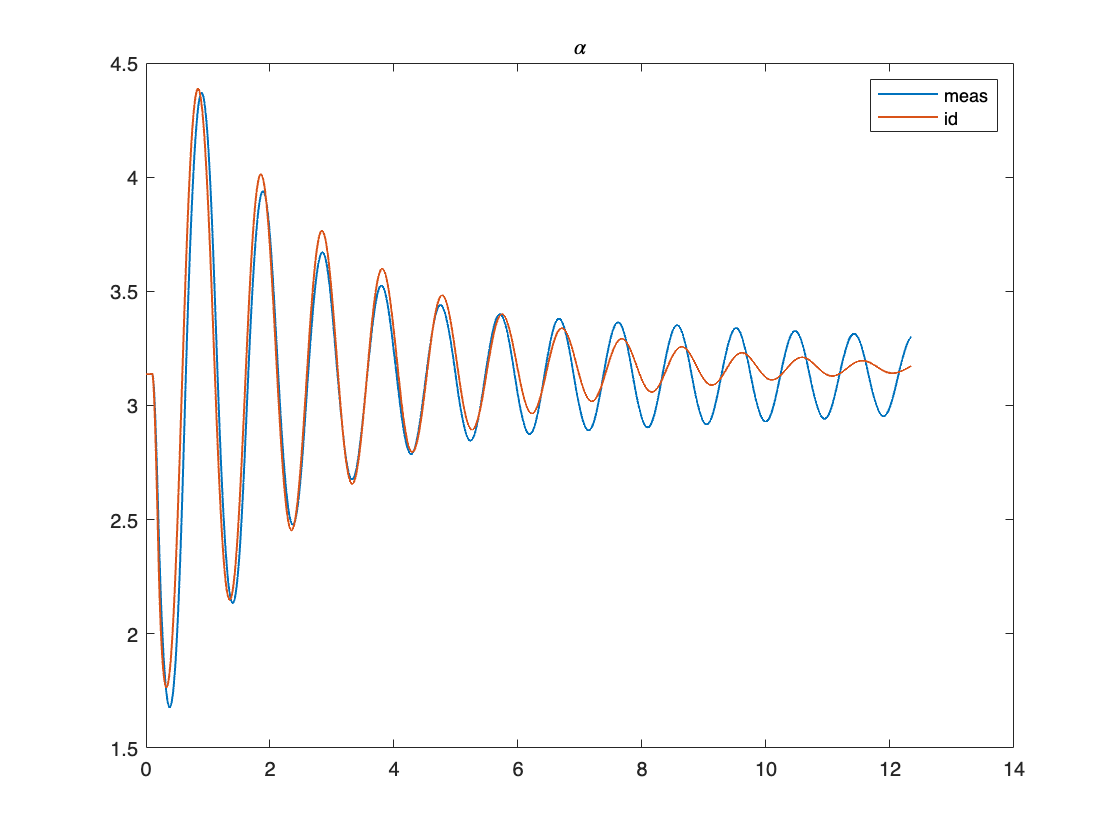

alpha_comp = ysim(2,:)-sim_dist.OutputData';
figure,plot(Time_vec,ymeas(2,:),Time_vec,alpha_comp,LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('meas','id')

### Disturbance Estimation

Most likely the discrepancy between the identified model and the data is due to the effect of the encoder cable on the movement of the system. Here we'll try to fit a TF linear model to estimate the disturbance using some ARMA model.

#### Hyp: the disturbance signal from the cable

**Remark: here the disturbance has been estimated from the validation set**

We assume that our identified model is correct, aka is able to grasp most of the non linear behaviour of the real system. So first we'll consider the difference in the time response between the simulated and measured alpha.

% sim_alpha = ysim(2,:);
% dist = ymeas(2,:) - sim_alpha;
% plot(Time_vec,dist)
% dist_data = iddata(dist',ymeas(1,:)',Ts); % time serie data of disturbance
% advice(dist_data)
% dist_sys = tfest(dist_data,3);
% compare(dist_data,dist_sys)

#### Plot identified model minus disturbance estimation

## Save Identified Parameters

% save("th_id.mat",'id_param'); % commented to avoid overwriting